这个实时脚本是用来画图展示生成的Data和HVval的相关信息

# train_data

Data: [1000000, 100, 3]

HVval: [1000000, 1]

load('//10.20.2.245/datasets/HVC-Net-datasets/data/test_data_M3_0.mat')
dataset_num = size(Data, 1)

dataset_num = 1000000

data_num = size(Data, 2)

data_num = 100

M = size(Data, 3)

M = 10

## Plot of HVval

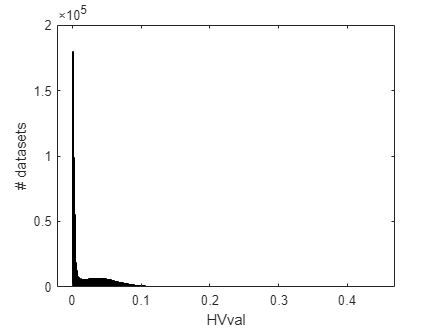

% 创建 HVval 的 histogram
h2 = histogram(HVval,'DisplayName','HVval');

% 添加 xlabel 和 title
xlabel('HVval')
ylabel('# datasets')

% title('HVval')
% legend

## Plot of HVCval

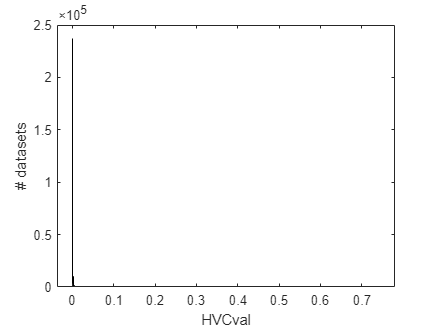

% 创建 HVval 的 histogram
h2 = histogram(HVCval,'DisplayName','HVCval');

% 添加 xlabel 和 title
xlabel('HVCval')
ylabel('# datasets')

% title('HVval')
% legend

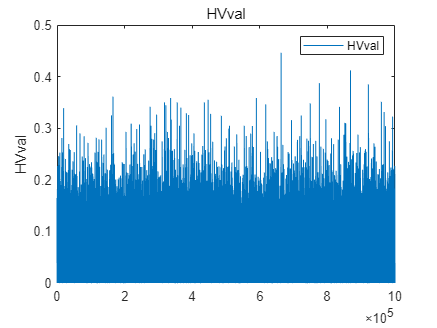

% 创建 HVval 的 plot
h3 = plot(HVval,'DisplayName','HVval');

% 添加 ylabel, title 和 legend
ylabel('HVval')
title('HVval')
legend

## Plot of Num_points in Each Dataset

num_of_points = sum(~isnan(Data(:,:,1)),2);

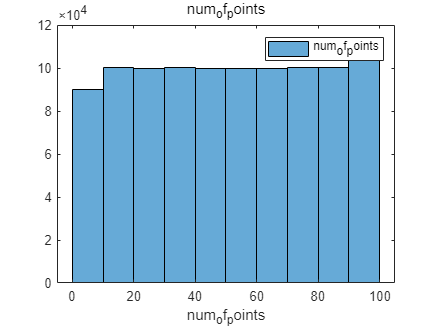

% 创建 num_of_points 的 histogram
h4 = histogram(num_of_points,'NumBins',10,'DisplayName','num_of_points');

% 添加 xlabel 和 title
xlabel('num_of_points')
title('num_of_points')
legend

## Details of Dataset

idx =10000

idx = 10000

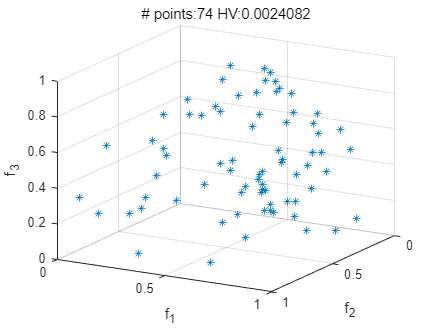

f_1 = Data(idx,:,1);
f_2 = Data(idx,:,2);
f_3 = Data(idx,:,3);
num_points = sum(~isnan(f_1));
% 创建 f_1, f_2, 和 f_3 的 scatter3
s = scatter3(f_1,f_2,f_3,'Marker','*');

% 添加 xlabel, ylabel, zlabel, title 和 legend
xlabel('f_1')
ylabel('f_2')
zlabel('f_3')
title(['# points:', int2str(num_points), ' HV:', num2str(HVval(idx))])
view(30,20)
set(gca, 'YDir', 'reverse')